# Gaussian Elimination with Backward Substitution

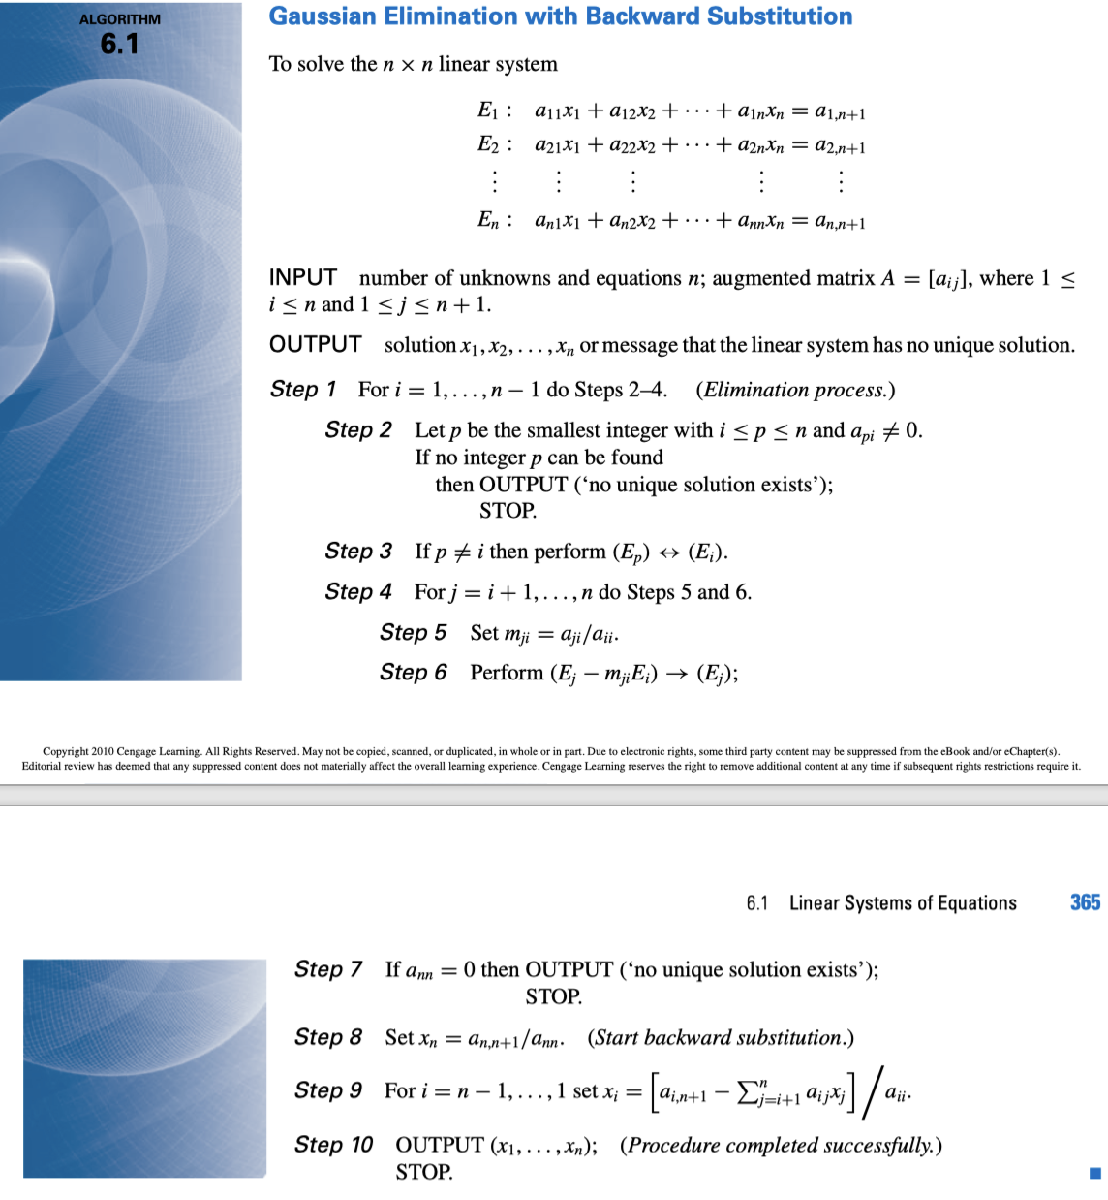

clc;clear;close all;

A=[4.3,6.6,-5.3,6.8;
    2.5,-1.2,+6.6,-2.0;
    5.4,2.2,-2.6,3.5;
    -7.2,5.3,-1.3,4.9];
B=[48.81;
    -30.50;
    45.69;
    -18.15];

Ag={};                                                  %Create a cell array to store each matrix
Aau=[A,B];                                              %Generate the augmented matrix
Ag{1}=Aau;                                              %Store the first initial matrix
[n,b]=size(A);
m=[];
for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    while Aau(p,i)==0 & p <= n-1    
        p=p+1;
    end
    if p==n & Aau(p,i)==0
        disp("No unique solution found, please check");
        break
    end
    Atemp=Aau(i,:);
    Aau(i,:)=Aau(p,:);
    Aau(p,:)=Atemp;
    for j=i+1:n
        m(j,i)=Aau(j,i)/Aau(i,i);
        Aau(j,:)=Aau(j,:)-m(j,i).*Aau(i,:);
    end
    Ag{i +1}=Aau;
end

if Aau(n,n)== 0
    disp("No unique Solution Exist");
else


    % Start the backward substituition
    x=[];
    x(n)=Aau(n,n+1)/Aau(n,n);
    
    for i=n-1:-1:1
        sum=0;
        for j=i+1:n
            sum=sum+Aau(i,j)*x(j);
        end
        x(i)=(Aau(i,n+1)-sum)/Aau(i,i);
    end
end


% modify into LU factorization

L2=eye(n);
L1=zeros(4,4);
L1(2:n,1:n-1)=m(2:end,:);
L=L1+L2;
disp(L);
U=Aau(:,1:n);

    1.0000         0         0         0
    0.5814    1.0000         0         0
    1.2558    1.2087    1.0000         0
   -1.6744   -3.2461   -2.7795    1.0000

